# TDA analysis of HCP Individual Contrasts

% Set project root
projectRoot = ''; 

% Add access to brain connectivity toolbocx (BCT)
bctFolder = fullfile(projectRoot, 'Code', '2019_03_03_BCT');
addpath(genpath(bctFolder));

% Build file/folder paths
behavFile = fullfile(projectRoot, 'HCP_behaviouraldata.xlsx');
tfmriFolder = fullfile(projectRoot, 'individual_tfmri_csv', 'output');
sub1File = fullfile(projectRoot, 'matching_sub1.csv');
sub2File = fullfile(projectRoot, 'matching_sub2.csv');

% Get subject numbers from filenames
files = dir(fullfile(tfmriFolder, '*_FAoutput.rds'));
subject_numbers = erase({files.name}, '_FAoutput.rds');

% Load logic for cohort 1 and 2
sub1_logic = readtable(sub1File);
sub2_logic = readtable(sub2File);

% Load contrast matrix of cohorts
load(fullfile(projectRoot, 'contrasts_all_2d_sub1.mat'));     % N×347
contrasts_all_2d_sub1 = data;
load(fullfile(projectRoot, 'row_labels_sub1.mat'));           % cell array of N
row_labels_sub1 = rowNames;

load(fullfile(projectRoot, 'contrasts_all_2d_sub2.mat'));     % M×347
contrasts_all_2d_sub2 = data;
load(fullfile(projectRoot, 'row_labels_sub2.mat'));           % cell array of M
row_labels_sub2 = rowNames;

## Specify cohort 1 or 2

cohort = 1; % 1 or 2

if cohort == 1
    data = contrasts_all_2d_sub1;
    rowNames = row_labels_sub1;
    suffix = '1';
elseif cohort == 2
    data = contrasts_all_2d_sub2;
    rowNames = row_labels_sub2;
    suffix = '2';
else
    disp("Specify cohort")
end

## Demean and normalize contrast data

% demean participants based on individual scores
subject_ids = cellfun(@(x) split(x, '_'), rowNames, 'UniformOutput', false);
subject_ids = cellfun(@(x) x{2}, subject_ids, 'UniformOutput', false);
subject_ids_numeric = cellfun(@str2double, subject_ids);

data_zscore_subjwise = [];
for s = 1:1:max(subject_ids_numeric)
    tmp = find(subject_ids_numeric==s);
    data_zscore_subjwise = [data_zscore_subjwise; zscore(data(tmp,:))];
end
data = data_zscore_subjwise;

% check for dead columns
bad_columns = find(var(data) == 0)


bad_columns =

  1×0 empty double row vector



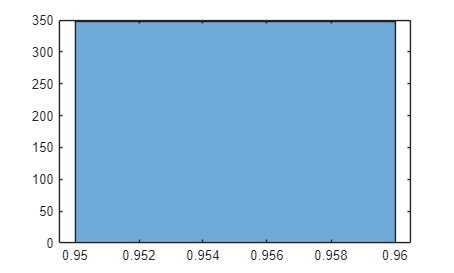

data(:,bad_columns) = [];

column_variances = var(data, 0, 1); 
figure;
histogram(column_variances, 'BinWidth', 0.01);

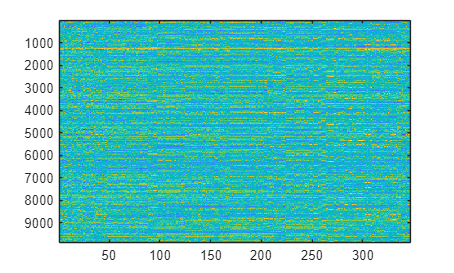


imagesc(data)

## # Running Mapper (No need to re-run if output is saved)

% metricType = 'euclidean';
% ndim = 2;
% conn = .95;
% 
% %Find optimal mapper parameters then run mapper
% [num_k, res_val, gain_val, num_bin_clusters] = findMapperParameters(data, metricType, ndim, .95);
% 
% % Run Mapper
% [nodeTpMat, nodeBynode, tpMat, filter, stress, dist_geo_wtd] = runBDLMapper(data, metricType, res_val, gain_val, num_k, num_bin_clusters, ndim);
% 
% % Visualize nodeBynode matrix
% figure;
% plot(graph(nodeBynode), 'Layout','force','UseGravity','on')
% 
% % Visualize tpMat matrix
% figure;
% plot(graph(tpMat), 'Layout','force','UseGravity','on')
% 
% % # nodeTpMat is a node by row (factor/subject) matrix: which row belong to which node
% % # nodeBynode is a node by node binary matrix: which nodes connect
% % # tpMat is a row by row matrix: the number of nodes shared for rows (factors/subjects)
% 
% % Save the variables into the specified file
% outputFileName = fullfile(projectRoot, sprintf('figures/rdochcp_contrastmapper_subs%s', suffix)); % _subs1 or _subs2
% save(outputFileName, 'nodeTpMat', 'nodeBynode', 'tpMat', 'filter', 'stress', 'dist_geo_wtd');

## 1) RDoC domain labeled contrast mapper

## Specify cohort 1 or 2 for subsequent analyses

cohort = 1; % 1 or 2

% Specify rdochcp_contrastmapper_subs1 or ..._subs2 for cohort 1 or cohort 2 
if cohort == 1
    load('rdochcp_contrastmapper_subs1.mat');
    suffix = '1';
elseif cohort == 2
    load('rdochcp_contrastmapper_subs2.mat');
    suffix = '2';
else
    disp("Specify cohort")
end

## Plot RDoC Mapper graph

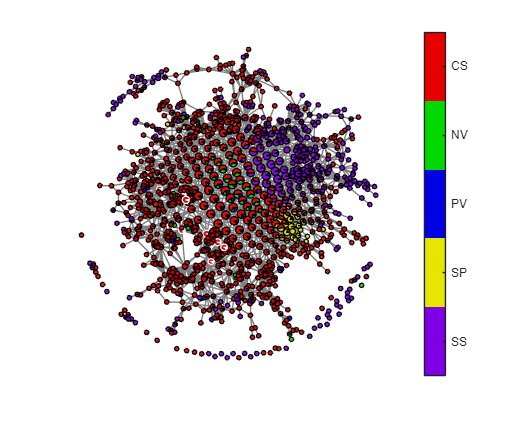

Elapsed time is 8.085254 seconds.


% Control conditions are CS
labels = {'NV-E1', 'CS-E2', 'NV-G1', 'PV-G2', 'CS-L1', 'CS-L2', 'CS-M1', 'SS-M2', 'SS-M3', 'SS-M4', 'SS-M5', 'SS-M6', 'CS-R1', 'CS-R2', 'CS-S1', 'SP-S2', 'CS-W1', 'CS-W2', 'CS-W3', 'CS-W4', 'CS-W5', 'CS-W6', 'CS-W7', 'CS-W8'};

% Get unique domains and assign each a numeric index
domains_rdoc = cellfun(@(x) x(1:2), labels, 'UniformOutput', false);
[unique_domains_rdoc, ~, domain_indices_rdoc] = unique(domains_rdoc);

% Determine number of subjects and maps
[n_nodes, n_total_maps] = size(nodeTpMat);
n_maps_per_subject = 24;
n_subjects = n_total_maps / n_maps_per_subject;

% Check divisibility
if mod(n_total_maps, n_maps_per_subject) ~= 0
    error('nodeTpMat columns not divisible by 24. Check input data.');
end

% Repeat domain index for each subject
domain_indices_all_rows = repmat(domain_indices_rdoc(:), n_subjects, 1);
comm = domain_indices_all_rows;

[nodeComm, prop_nodes] = computeProportionCategorical(nodeTpMat, comm); %color_indices links each factor with the highest loading map
[hubness90, hubness95, hubness99] = computeHubness(nodeBynode, degrees_und(nodeBynode));

color = [
    .9, 0, 0;     % Red
    0, .85, 0;     % Green
    0, 0, .9;     % Blue
    .9, .9, 0;     % Yellow
    .5, 0, .9     % Purple
    % .6, .6, .6      % Controls
];

saveit = 1; % 1 to save, 0 to not save
drawd3graph(nodeBynode, nodeComm, prop_nodes, color, fullfile(projectRoot, sprintf('figures/rdochcp_contrastmapper_rdoc%s_NVG1', suffix)), hubness90, unique_domains_rdoc, saveit);

## Calculate modularity

modularity = calMod(nodeBynode, nodeComm)
n_iter = 100;
rng("default")
[p_value, null_modularities] = testModularitySignificance(comm, modularity, n_iter, nodeTpMat, nodeBynode);
saveas(gcf, fullfile(projectRoot, sprintf('figures/modularity_contrastmapper_rdoc%s.png', suffix)));

## Compute correlation of RDoC Mapper prop_nodes

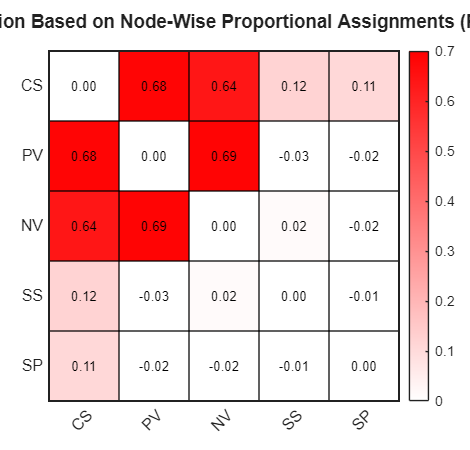

% Compute correlation matrix
R = corr(prop_nodes);

% Set diagonal to 0
R(1:size(R,1)+1:end) = 0;

% Compute row + column sums
row_col_sums = sum(R, 2) + sum(R, 1)';  % column vector
[~, new_order] = sort(row_col_sums, 'descend');

% Reorder R
R_sorted = R(new_order, new_order);
labels_sorted = unique_domains_rdoc(new_order);
row_sums_sorted = sum(R_sorted, 2);

cell_size = 70;
plot_fixed_square_heatmap(R_sorted, labels_sorted, labels_sorted, ...
    'Correlation Based on Node-Wise Proportional Assignments (RDoC)', ...
    [100, 100], cell_size, ...
    [linspace(1,1,256)', linspace(1,0,256)', linspace(1,0,256)'], ...
    [0, 0.7], ...
    fullfile(projectRoot, sprintf('figures/corrpropnode_rdoc%s_NVG1.png', suffix)));

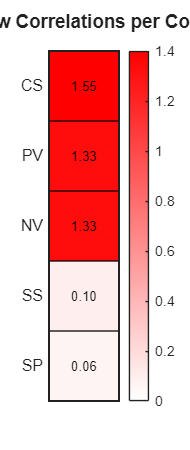


% --- Figure 2: Single-Column Sum Heatmap ---
plot_fixed_square_heatmap(row_sums_sorted, '', labels_sorted, ...
    'Sum of Row Correlations per Community', ...
    [750, 100], cell_size, ...
    [linspace(1,1,256)', linspace(1,0,256)', linspace(1,0,256)'], ...
    [0, 1.4], ...
    fullfile(projectRoot, sprintf('figures/corrsum_rdoc%s_NVG1.png', suffix)));

## 2) Data-driven community labeled contrast mapper

## Specify cohort 1 or 2 for subsequent analyses

cohort = 1; % 1 or 2

% Load community centroids of cohort 1 and 2
load(fullfile(projectRoot, 'comm_centroid1.mat')); % fscores 
% load(fullfile(projectRoot, 'comm_centroid2.mat')); % fscores

% Load _sub1 or _sub2 for cohort 1 or 2 for subsequent analyses
if cohort == 1
    load('rdochcp_contrastmapper_subs1.mat');
    load(fullfile(projectRoot, 'rdochcp_allsubs1_community.mat')); % Load communities from R code
    factor_data = readtable(fullfile(projectRoot, 'ddfactors_subs1_nog_hcp.xlsx'));
    comm_centroid = comm_centroid1;
    suffix = '1';
elseif cohort == 2
    load('rdochcp_contrastmapper_subs2.mat');
    load(fullfile(projectRoot, 'rdochcp_allsubs2_community.mat')); % Load communities from R code
    factor_data = readtable(fullfile(projectRoot, 'ddfactors_subs2_nog_hcp.xlsx'));
    comm_centroid = comm_centroid2;
    suffix = '2';
else
    disp("Specify cohort")
end

## Showing communities across factor scores

% Demean participants based on individual scores
rowNames = factor_data{:, 1};
factor_data(:, 1) = [];
factor_data.Properties.RowNames = rowNames;
factor_data = factor_data{:, :}; %turns the table into an array

subject_ids = cellfun(@(x) split(x, '_'), rowNames, 'UniformOutput', false);
subject_ids = cellfun(@(x) x{2}, subject_ids, 'UniformOutput', false);
subject_ids_numeric = cellfun(@str2double, subject_ids);

factor_data_zscore_subjwise = [];
for s = 1:1:max(subject_ids_numeric)
    tmp = find(subject_ids_numeric==s);
    factor_data_zscore_subjwise = [factor_data_zscore_subjwise; zscore(factor_data(tmp,:))];

end
factor_data = factor_data_zscore_subjwise;

max(ciu) % This should be 4/5 modules for cohort 1/2 respectively

ans = 4

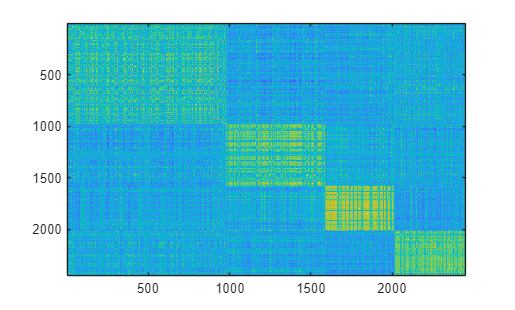

[comm, comm2, ~] = arrangeComm(ciu, corr(factor_data'));
imagesc(comm) %visualizing the communities

## Plot Data-driven Mapper graph

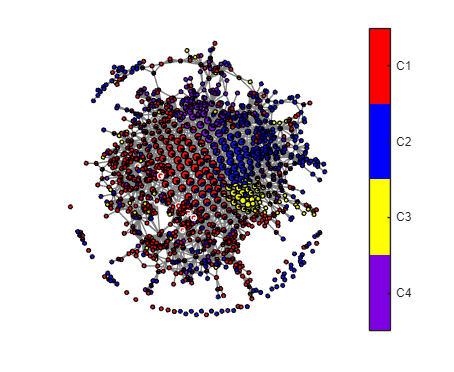

Elapsed time is 0.000082 seconds.


% Reorder the community centroids of cohort 2 to 1a, 1b, 2, 3, 4 to match the 4 centroids in cohort 1
if size(comm_centroid, 1) == 5
    comm_centroid = comm_centroid([1 5 3 2 4], :); 
end

% Compute correlation between each row of data and each centroid
n_rows = size(data, 1);
n_centroids = size(comm_centroid, 1);

correlations = zeros(n_rows, n_centroids);

for i = 1:n_centroids
    % Compute correlation between each row in data and the i-th centroid
    c = corr(data', comm_centroid(i, :)');  % returns 9888 x 1
    correlations(:, i) = c;
end

% Get index of the max correlation for each row
[~, best_centroid_idx] = max(correlations, [], 2);  % 9888 x 1
comm = best_centroid_idx;

if size(comm_centroid, 1) == 4
    unique_comms = {"C1", "C2", "C3", "C4"};
elseif size(comm_centroid, 1) == 5
    unique_comms = {"C1a", "C1b", "C2", "C3", "C4"};
end 

[nodeComm, prop_nodes] = computeProportionCategorical(nodeTpMat, comm); %color_indices links each factor with the highest loading map
[hubness90, hubness95, hubness99] = computeHubness(nodeBynode, degrees_und(nodeBynode));

if size(comm_centroid, 1) == 5
color = [
    1, 0, 0;   % Red
    0, 1, 0;   % Green
    0, 0, 1;   % Blue
    1, 1, 0;    % Yellow
    .5, 0, .9;    % Purple
];
elseif size(comm_centroid, 1) == 4
    color = [
    1, 0, 0;   % Red
    0, 0, 1;   % Blue
    1, 1, 0;    % Yellow
    .5, 0, .9;    % Purple
];
end 

saveit = 0; % 0 to not save, 1 to save
drawd3graph(nodeBynode, nodeComm, prop_nodes, color, fullfile(projectRoot, sprintf('figures/rdochcp_contrastmapper_comm%s', suffix)), hubness90, unique_comms, saveit);

% Calculate modularity
modularity = calMod(nodeBynode, nodeComm)

modularity = 0.3803

n_iter = 5000;
rng("default")
[p_value, null_modularities] = testModularitySignificance(comm, modularity, n_iter, nodeTpMat, nodeBynode);
saveas(gcf, fullfile(projectRoot, sprintf('figures/modularity_contrastmapper_comm%s.png', suffix)));

## Compute correlation of Data-driven Mapper prop_nodes

modularity = calMod(nodeBynode, nodeComm)
n_iter = 5000;
rng("default")
% [p_value, null_modularities] = testModularitySignificance(comm, modularity, n_iter, nodeTpMat, nodeBynode);
% saveas(gcf, fullfile(projectRoot, 'figures', 'modularity_contrastmapper_comm2.png');

% Compute off-diagonal correlation matrix
R = corr(prop_nodes);
R(1:size(R,1)+1:end) = 0;  % Set diagonal to NaN

% Compute row + column sums
row_col_sums = sum(R, 2) + sum(R, 1)';
[~, sort_idx] = sort(row_col_sums, 'descend');

% Reorder R and labels
R_sorted = R(sort_idx, sort_idx);
labels_sorted = unique_comms(sort_idx);
row_sums_sorted = sum(R_sorted, 2);  % for single-column heatmap

% Define appearance
cell_size = 70;
cmap = [linspace(1,1,256)', linspace(1,0,256)', linspace(1,0,256)'];

% ---- Figure 1: full matrix ----
plot_fixed_square_heatmap(R_sorted, labels_sorted, labels_sorted, ...
    'Correlation Based on Node-Wise Proportional Assignments (DD)', ...
    [100, 100], cell_size, cmap, [0, 0.7], ...
    fullfile(projectRoot, sprintf('figures/corrprop_contrastmapper_comm%s.png', suffix)));

% % ---- Figure 2: row sums ----
plot_fixed_square_heatmap(row_sums_sorted, '', labels_sorted, ...
    'Sum of Row Correlations per Community', ...
    [750, 100], cell_size, cmap, ...
    [0, 1.4], ...
    fullfile(projectRoot, sprintf('figures/corrsum_contrastmapper_comm%s.png', suffix)));

## 3) Violin plots of jackknife bootstrap modularity

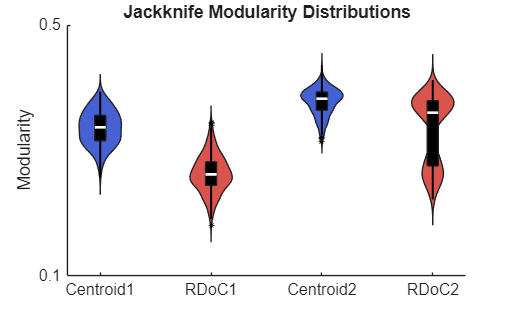

load(fullfile(projectRoot, 'modularity_jackknife_results_NVG1')) % Cohort 1 results from Jackknife bootstrapping R code 
load(fullfile(projectRoot, 'modularity_jackknife_results_NVG1_sub2')) % Cohort 2 results from Jackknife bootstrapping R code

% Get lengths
n1 = length(mod_centroid_sub1);
n2 = length(mod_centroid_sub2);
n_max = max(n1, n2);

% Pad with NaNs to match length
mod_centroid_sub2(end+1:n_max,1) = NaN;
mod_rdoc_sub2(end+1:n_max,1) = NaN;

% Concatenate
Y = [mod_centroid_sub1, mod_rdoc_sub1, mod_centroid_sub2, mod_rdoc_sub2];

% Define a unique group for each column to apply per-column coloring
group_idx = [1, 2, 3, 4];  % fake group labels to force 4 colors

% Define 4 colors: [Centroid Sub1, RDoC Sub1, Centroid Sub2, RDoC Sub2]
color_centroid = [0.27, 0.38, 0.83];  % blue
color_rdoc     = [0.85, 0.33, 0.30];  % red
colors = [color_centroid; color_rdoc; color_centroid; color_rdoc];

% Repeat group labels for each data point
groups = repelem(group_idx, size(Y, 1))';

% Reshape data and group vector for column-wise input
Y_flat = Y(:);
group_labels = repelem(1:4, size(Y,1))';

% Prepare as matrix with one column and set group vector
figure;
daviolinplot(Y_flat, 'groups', group_labels, ...
    'colors', colors, ...
    'violin', 'full', ...
    'box', 2, ...
    'xtlabels', {'Centroid1', 'RDoC1', 'Centroid2', 'RDoC2'});
ylim([0.1 0.5]);
yticks([0.1 0.5]);
ylabel('Modularity');
title('Jackknife Modularity Distributions');
set(gca, 'FontSize', 12);


% Save the plot
% saveas(gcf, fullfile(projectRoot, 'figures', 'modularity_jackknifebs_NVG1_violinplot.png'));

## Wilcoxon signed-rank test

% Test for Sub1
[p_sub1, h_sub1, stats_sub1] = signrank(mod_centroid_sub1, mod_rdoc_sub1);
% Test for Sub2
[p_sub2, h_sub2, stats_sub2] = signrank(mod_centroid_sub2, mod_rdoc_sub2);

fprintf('Sub1 Centroid vs RDoC: p = %.4f, z = %.2f\n', p_sub1, stats_sub1.zval);

Sub1 Centroid vs RDoC: p = 0.0000, z = 17.59


fprintf('Sub2 Centroid vs RDoC: p = %.4f, z = %.2f\n', p_sub2, stats_sub2.zval);

Sub2 Centroid vs RDoC: p = 0.0000, z = 14.76



% Paired t-test for Sub1
[~, p_sub1, ~, stats_sub1] = ttest(mod_centroid_sub1, mod_rdoc_sub1);
% Paired t-test for Sub2
[~, p_sub2, ~, stats_sub2] = ttest(mod_centroid_sub2, mod_rdoc_sub2);

fprintf('Sub1 Centroid vs RDoC: p = %.4f, t = %.2f, df = %d\n', ...
    p_sub1, stats_sub1.tstat, stats_sub1.df);

Sub1 Centroid vs RDoC: p = 0.0000, t = 79.63, df = 411


fprintf('Sub2 Centroid vs RDoC: p = %.4f, t = %.2f, df = %d\n', ...
    p_sub2, stats_sub2.tstat, stats_sub2.df);

Sub2 Centroid vs RDoC: p = 0.0000, t = 19.98, df = 328


## Functions

function [nodeTpMat, nodeBynode, tpMat, filter, stress, dist_geo_wtd] = runBDLMapper(data, metricType, res_val, gain_val, num_k, num_bin_clusters,  ndim)

    X = data;
    opt = statset('display','iter');
    
    resolution = [res_val res_val];
    gain = gain_val;
    
    fprintf(1,'Estimating distance matrix\n');
    tic
    distMat = estimateDistance(X, metricType);
    toc
    
    %--Manish Version--%
    fprintf(1,'Estimating knn graph\n');
    tic
    % create knn graph, estimate geodesic distances, embed using cmdscale and apply mapper
    [~, ~, ~, ~, knnGraph_dense_wtd_conn]= createPKNNG_bdl(distMat, num_k);

    % date: Mar 19, 2024
    % making a change here using knnGraph_dense_wtd_conn instead of
    % binarized
    % knn_g_wtd = graph(knnGraph_dense_bin_conn);
    knn_g_wtd = graph(knnGraph_dense_wtd_conn);

    % estimate geodesic distances
    % date: Mar 19, 2024
    % making a change here using auto method instead of positive; also
    % removing rounding.
    % dist_geo_wtd = round(distances(knn_g_wtd,'Method','positive'));
    dist_geo_wtd = distances(knn_g_wtd);
    toc
    
    fprintf(1,'Estimating embedding\n');
    tic
    
    % embed using cmdscale
    if sum(sum(isinf(dist_geo_wtd))) > 0
        fprintf(2,'Error geodesic distances have an infinite value, fixing it by adding a large value instead of Inf\n');
        dist_geo_wtd(find(isinf(dist_geo_wtd))) = max(dist_geo_wtd(~isinf(dist_geo_wtd)))+10;
        
        % date: Mar 19, 2024
        % making a change to metric MDS from classic MDS and saving stress
        % values to determine the quality or goodness of fit. Also using
        % Sammon as a stress measure to better preserve smaller distances.
        %[y,e] = cmdscale(dist_geo_wtd);
        [y, stress] = mdscale(dist_geo_wtd, ndim, 'Options', opt, 'Start', 'cmdscale', 'Criterion', 'sammon');
    else        
        %[y,e] = cmdscale(dist_geo_wtd);
        [y, stress] = mdscale(dist_geo_wtd, ndim, 'Options', opt, 'Start', 'cmdscale', 'Criterion', 'sammon');
    end
  
    filter = [y(:,1), y(:,2)];
    % modifying filter by taking a zscore and then log transform Updated
    % Nov 12, 2022
    %filter = real([log(zscore(filter(:,1))) log(zscore(filter(:,2)))]);
    toc
    
    fprintf(1,'Running mapper\n');
    tic
    
    
    %[adja, adja_pruned, pts_in_vertex, pts_in_vertex_pruned] = mapper2d_bdl_nonmetric(distMat, filter, resolution, gain, num_bin_clusters);
    [adja, adja_pruned, pts_in_vertex, pts_in_vertex_pruned] = mapper2d_bdl_hex_binning(distMat, filter, resolution, gain, num_bin_clusters, 3); %using triangulation, as higher values induce too many connections
    %--End Manish Version--%
    toc
    
    fprintf(1,'Creating final output\n');
    tic
    % creating matrices for d3 visualization
    numNodes = length(pts_in_vertex_pruned);
    numTp = size(X,1);
    nodeTpMat = zeros(numNodes, numTp);
    for node = 1:1:numNodes
        tmp = pts_in_vertex_pruned{node};
        nodeTpMat(node, tmp) = 1;
    end

    nodeBynode = adja_pruned;
    tpMat = getMatTp_wtd(nodeBynode, nodeTpMat);
    fprintf(1,'Done\n');
    toc

end


function [num_k, res_val, gain_val, num_bin_clusters] = findMapperParameters(data, metricType, ndim, conn)

    num_k = floor(sqrt(size(data,1))); %sqrt of number of time points; from this paper - https://link.springer.com/article/10.1007/s10462-017-9593-z

    opt = statset('display','iter');
    distMat = squareform(pdist(data, metricType)); 
    [~, ~, ~, ~, knnGraph_dense_wtd_conn]= createPKNNG_bdl(distMat, num_k);
    knn_g_wtd = graph(knnGraph_dense_wtd_conn);
    dist_geo_wtd = distances(knn_g_wtd);
    
    if sum(sum(isinf(dist_geo_wtd))) > 0
        fprintf(2,'Error geodesic distances have an infinite value, fixing it by adding a large value instead of Inf\n');
        dist_geo_wtd(find(isinf(dist_geo_wtd))) = max(dist_geo_wtd(~isinf(dist_geo_wtd)))+10;        
        [y, ~] = mdscale(dist_geo_wtd, ndim, 'Options', opt, 'Start', 'cmdscale', 'Criterion', 'sammon');
    else        
        [y, ~] = mdscale(dist_geo_wtd, ndim, 'Options', opt, 'Start', 'cmdscale', 'Criterion', 'sammon');
    end
    
    [~,bw,~,~]=KDE2_eff(y(:,1), y(:,2));

    res_val = ceil(max(max(y)-min(y))./(2*mean(bw))); % (2)x bw -> mean instead of min or max

    num_bin_clusters = 10; % todo optimize these too someday
    max_conn_comp = [];
    gain_vals = 50:5:90;
    for gain = gain_vals
        gain
        [~, nodeBynode, ~, ~] = mapper2d_bdl_hex_binning(distMat, y, [res_val res_val], gain, num_bin_clusters, 3);
        G = graph(nodeBynode);
        [~, binsizes] = conncomp(G);
        max_conn_comp = [max_conn_comp; max(binsizes)./size(nodeBynode,1)];
    end

    gain_val = find(max_conn_comp>=conn); % 75% connectivity of the graph for individuals; 95% for groups
    gain_val = gain_vals(gain_val(1)); 
end


function [knnGraphTbl, knnGraph_dense_bin, knnGraph_dense_wtd, knnGraph_dense_bin_conn, knnGraph_dense_wtd_conn]= createPKNNG_bdl(distMat, num_k)
   % create neighborhood graph
   knnGraphTbl = zeros(size(distMat,1), num_k);
   knnGraph_bin = zeros(size(distMat));
   knnGraph_wtd = zeros(size(distMat));
   for n = 1:1:size(distMat,1)
      [tmp idx] = sort(distMat(n,:),'ascend');
      knnGraphTbl(n,:) = idx(2:2+num_k-1);
      for l = 1:1:num_k
         knnGraph_bin(n, knnGraphTbl(n,l)) = 1; 
         knnGraph_wtd(n, knnGraphTbl(n,l)) = distMat(n,knnGraphTbl(n,l)); 
          
      end
   end
   
   % remove outliers in knn graph to find densely connected subgraphs
   % first remove non-reciprocal connections
   knnGraph_dense_bin = knnGraph_bin;
   knnGraph_dense_wtd = knnGraph_wtd;
   for n = 1:1:size(distMat,1)
      tmp = knnGraphTbl(n,:);
      for l = 1:1:num_k         
         if ~ismember(n,knnGraphTbl(tmp(l),:))
             knnGraph_dense_bin(n,tmp(l)) = 0;
             knnGraph_dense_bin(tmp(l),n) = 0;

             knnGraph_dense_wtd(n,tmp(l)) = 0;
             knnGraph_dense_wtd(tmp(l),n) = 0;             
         end         
      end       
   end
   
   % connect disconnected components of the graph
   g = graph(knnGraph_dense_wtd);
   knnGraph_dense_wtd_conn = knnGraph_dense_wtd;
   knnGraph_dense_bin_conn = knnGraph_dense_bin;
   bins = conncomp(g);
   nComp = max(bins);
   if nComp > 1 
      for c = 1:1:nComp          
          for d = c+1:1:nComp
              nodes_c = find(bins==c);
              nodes_d = find(bins==d);
              max_edge_c = max(max(knnGraph_dense_wtd(nodes_c, nodes_c)));
              max_edge_d = max(max(knnGraph_dense_wtd(nodes_d, nodes_d)));
              if length(nodes_d) == 1
                 [val, best_nodes_c] = min(distMat(nodes_d, nodes_c));
                 knnGraph_dense_wtd_conn(nodes_d, best_nodes_c) = val * exp(val/max_edge_c);
                 knnGraph_dense_wtd_conn(best_nodes_c, nodes_d) = knnGraph_dense_wtd_conn(nodes_d, best_nodes_c);
                 knnGraph_dense_bin_conn(nodes_d, best_nodes_c) = 1;
                 knnGraph_dense_bin_conn(best_nodes_c, nodes_d) = 1;
              elseif length(nodes_c) == 1
                 [val, best_nodes_d] = min(distMat(nodes_c, nodes_d));
                 knnGraph_dense_wtd_conn(nodes_c, best_nodes_d) = val * exp(val/max_edge_d);
                 knnGraph_dense_wtd_conn(best_nodes_d, nodes_c) = knnGraph_dense_wtd_conn(nodes_c, best_nodes_d);
                 knnGraph_dense_bin_conn(nodes_c, best_nodes_d) = 1;
                 knnGraph_dense_bin_conn(best_nodes_d, nodes_c) = 1;                  
              else % find the best pair of nodes between nodes_c and nodes_d that can be connected
                 tmp = distMat(nodes_c, nodes_d);
                 val = min(tmp(:));
                 [nodes_c_min, nodes_d_min] = find(tmp==val);
                 nodes_c_min = nodes_c(nodes_c_min);
                 nodes_d_min = nodes_d(nodes_d_min);
                 knnGraph_dense_wtd_conn(nodes_c_min, nodes_d_min) = val * exp(val/max(max_edge_c,max_edge_d));
                 knnGraph_dense_wtd_conn(nodes_d_min, nodes_c_min) = knnGraph_dense_wtd_conn(nodes_c_min, nodes_d_min);
                 knnGraph_dense_bin_conn(nodes_c_min, nodes_d_min) = 1;
                 knnGraph_dense_bin_conn(nodes_d_min, nodes_c_min) = 1;
              end                  
          end          
      end
   end
end


function [fx,h,Xrange,Yrange]=KDE2_eff(Xi,Yi,Xrange,Yrange,h)
    % Revised by Taesam Lee
    % for large data set
    %
    % Kernel Density Estimate for 2 vairable
    % for diagonal type h and multivariate normal kernel
    % Each "Smoothing parameter" h is estimated from the SJ method 
    % unless it is provided
    % The X and Y range is devided 30 along the min and max 
    % of historical data as a default
    %
    % Used subfunction : bandwidth_SJ.m
    %
    % Input
    % Xi Yi : Historical Data (n*1) vector with the same data length
    % h : bandwidth
    % Xrange, Yrange : nr*1 vector with same length
    %
    % Output
    % fx : Estiamted 2 variable density matrix (nr*nr) or 30*30(default)
    % h  : Sheather and Jones 
    % Xrange, Yrange - min~max with 30 (default)
    %
    % Programmed by Taesam Lee (02.16.2009)
    % Reference : Simonoff JS(1996)-Smoothing methods in Statistics
    % Example
    %[f,h,xr,yr]=KDE2_eff(X(1,1:1000)',Y(2,1:1000)')
    nL=length(Xi);
    if nargin<=2
        rax=range(Xi);
        ray=range(Yi);
        Xrange=linspace(min(Xi)-rax*0.1,max(Xi)+rax*0.1,100);
        Yrange=linspace(min(Yi)-ray*0.1,max(Yi)+ray*0.1,100);
        %Xrange=min(Xi):(max(Xi)-min(Xi))/29:max(Xi);
        %Yrange=min(Yi):(max(Yi)-min(Yi))/29:max(Yi);
    end
    if nargin<=4
        [a,b,h(1)]=ksdensity(Xi,0);
        [a,b,h(2)]=ksdensity(Yi,0);
        %[h(1)]=bandwidth_SJ2(Xi,'norm');
        %[h(2)]=bandwidth_SJ2(Yi,'norm');
    end
    nX=length(Xrange);
    nY=length(Yrange);
    for ix=1:nX
        for iy=1:nY
            u1=(Xrange(ix)-Xi)/h(1);
            u2=(Yrange(iy)-Yi)/h(2);
            u=[u1,u2]';
            Kd_u=1/(2*pi)^(2/2)*exp(-1/2*sum(u.^2));
            %for is=1:nL
            %    Kd_u(is)=1/(2*pi)^(2/2)*exp(-1/2*u(:,is)'*u(:,is));
            %end
            fx(ix,iy)=mean(Kd_u)/prod(h);
        end
    end
end


function [adja, adja_pruned, pts_in_vertex, pts_in_vertex_pruned] = mapper2d_bdl_hex_binning(distMat, filter_values, num_intervals, percent_overlap, num_bins_clustering, nsides)

 %initialize variables
 vertex_index = 0;
 if ~exist('nsides','var')
    nsides = 6; %for hex, and 4 for regular.
 end

 % indexed from 1 to the number of vertices
 level_of_vertex = [];
 pts_in_vertex = [];
 
 % indexed from 1 to the number of levels
 pts_in_level = {};
 vts_in_level = {}; 
 
 filter_min_1 = floor(min(filter_values(:,1)));
 filter_max_1 = ceil(max(filter_values(:,1)));
 filter_min_2 = floor(min(filter_values(:,2)));
 filter_max_2 = ceil(max(filter_values(:,2)));

 interval_length_1 = (filter_max_1 - filter_min_1) / (num_intervals(1) - (num_intervals(1) - 1) * percent_overlap/100 );
 interval_length_2 = (filter_max_2 - filter_min_2) / (num_intervals(2) - (num_intervals(2) - 1) * percent_overlap/100 );

 step_size_1 = interval_length_1 * (1 - percent_overlap/100);
 step_size_2 = interval_length_2 * (1 - percent_overlap/100);

 num_levels = num_intervals(1) * num_intervals(2);

 level_indices_1 = repmat(1:num_intervals(1), [1,num_intervals(2)]);
 level_indices_2 = reshape(repmat(1:num_intervals(2), num_intervals(1),1),[num_levels,1])';
 %figure; 
 for level = 1:1:num_levels
    level_1 = level_indices_1(level); 
    level_2 = level_indices_2(level);
    
    min_val_level_1 = filter_min_1 + (level_1-1)*step_size_1;
    min_val_level_2 = filter_min_2 + (level_2-1)*step_size_2;
    
    max_val_level_1 = min_val_level_1 + interval_length_1;
    max_val_level_2 = min_val_level_2 + interval_length_2;
    
    % step 1: find center of min & max and create hexagon ther
    % step 2: find pts that are within that hexagon
    % step 3: we will start intersecting
    center_level_1 = (min_val_level_1+max_val_level_1)./2;
    center_level_2 = (min_val_level_2+max_val_level_2)./2;
    hex_poly = nsidedpoly(nsides, 'Center', [center_level_1, center_level_2], 'SideLength',  (interval_length_1+interval_length_2)./2);  
    pts_level = isinterior(hex_poly, filter_values);
    %plot(hex_poly); hold on;
    %pts_level = (filter_values(:,1) >= min_val_level_1) & (filter_values(:,2) >= min_val_level_2) & (filter_values(:,1) <= max_val_level_1) & (filter_values(:,2) <= max_val_level_2);
    
    num_pts_level = sum(pts_level);
    pts_in_level{level} = find(pts_level);
    
    if num_pts_level == 0
       %fprintf(1,'Level set is empty\n');
       vts_in_level{level} = -1;
       continue;        
    elseif num_pts_level == 1
       %fprintf(1,'Level set has only 1 pt\n');
       num_vts_level = 1;
       cluster_indices_within_level = [1];
       vts_in_level{level} = vertex_index + (1:num_vts_level);
    elseif num_pts_level > 1
       %fprintf(1,'Level set has only %d pts\n', num_pts_level);
       level_distMat = distMat(pts_level, pts_level);
       level_max_dist = max(level_distMat(:));
       [Z, cutoff] = find_cluster_cutoff(level_distMat, num_bins_clustering);
       if cutoff <0
           fprintf(2,'cutoff <0\n');
           cutoff = 1;
           
       end
       cluster_indices_within_level = cluster(Z, 'cutoff',cutoff, 'criterion','distance');
       num_vts_level = max(cluster_indices_within_level);
       vts_in_level{level} = vertex_index + (1:num_vts_level);
    end
    
    for j = 1:1:num_vts_level
       vertex_index = vertex_index + 1;
       level_of_vertex(vertex_index) = level;
       pts_in_vertex{vertex_index} = pts_in_level{level}(cluster_indices_within_level==j);
        
    end
     
 end
 %scatter(filter_values(:,1), filter_values(:,2), 15,'k');
 % pruning nodes/vertices that have same number of points in them
 pts_in_vertex_pruned = pts_in_vertex;
 for i = 1:1:vertex_index
     for j = i:1:vertex_index
         if i == j
             continue;
         end
         k1 = pts_in_vertex{i};
         k2 = pts_in_vertex{j};
         if isequal(sort(k1),sort(k2))
             %fprintf(1,'found one vertex for pruning i=%d, j=%d\n', i,j);
             pts_in_vertex_pruned{j} = [];
         end
     end
 end
 tmp = {};
 k = 1;
 for i = 1:1:vertex_index
    if ~isempty(pts_in_vertex_pruned{i})
        tmp{k} = pts_in_vertex_pruned{i};
        k = k+1;
    end
 end
 pts_in_vertex_pruned = tmp;
 fprintf(1,'Pruning done\n');
 
 vertex_index_pruned = length(pts_in_vertex_pruned);
 adja_pruned =  zeros(vertex_index_pruned, vertex_index_pruned);
 for i = 1:1:vertex_index_pruned
     for j = i:1:vertex_index_pruned
         if i == j
             continue;
         end
         k1 = pts_in_vertex_pruned{i};
         k2 = pts_in_vertex_pruned{j};
         adja_pruned(i,j) = (length(intersect(k1,k2))>0);
         adja_pruned(j,i) = adja_pruned(i,j);
     end
 end
 fprintf(1,'Prunned Mapper Done\n');
 
 
 adja = zeros(vertex_index, vertex_index);
%  for i = 1:1:vertex_index
%      for j = i:1:vertex_index
%          if i == j
%              continue;
%          end
%          k1 = pts_in_vertex{i};
%          k2 = pts_in_vertex{j};
%          adja(i,j) = (length(intersect(k1,k2))>0);
%          adja(j,i) = adja(i,j);
%      end
%  end
%  fprintf(1,'Mapper Done\n');
 
end

function [Z, cutoff] = find_cluster_cutoff(distMat, num_bins_clustering)
   Z = linkage(distMat(tril(true(length(distMat)),-1))');
   if length(Z(:,3)) == 1 % only two points hence one cluster
       fprintf(1,'Only two points found for clustering\n');
       cutoff = Inf;
       return;
   end
   
   lens = [Z(:,3)' max(max(distMat))];
   [numBins, bc] = hist(lens, num_bins_clustering);
   z = find(numBins==0);
   if (sum(z) == 0)
       cutoff = Inf;
       return;
   else
       cutoff = bc(z(1)); % pickup the smallest index of z
   end


end


function distMat = estimateDistance(X, metricType)
    distMat = squareform(pdist(X, metricType));
end


function [p_value, null_modularities] = testModularitySignificance(comm, modularity, n_iter, nodeTpMat, nodeBynode)
% testModularitySignificance - Assess significance of modularity against a null model
%
% Inputs:
%   comm        - Original community labels (e.g., color_indices)
%   modularity  - Observed modularity value from real data
%   n_iter      - Number of null iterations
%   nodeTpMat   - Matrix linking factors to maps (for computeProportionCategorical)
%   nodeBynode  - Adjacency matrix used in modularity calculation
%
% Outputs:
%   p_value            - Empirical one-tailed p-value
%   null_modularities  - Vector of null modularity values

    null_modularities = zeros(n_iter, 1);

    for i = 1:n_iter
        % Shuffle community labels
        shuffled_indices = comm(randperm(length(comm)));

        % Recalculate nodeComm based on shuffled community labels
        [shuffled_nodeComm, ~] = computeProportionCategorical(nodeTpMat, shuffled_indices);

        % Compute modularity for shuffled assignment
        null_modularities(i) = calMod(nodeBynode, shuffled_nodeComm);
    end

    % Calculate empirical p-value (one-tailed test)
    p_value = mean(null_modularities >= modularity);

    % Display results
    fprintf('Observed modularity: %.4f\n', modularity);
    fprintf('Empirical p-value: %.4f\n', p_value);

    % Plot null distribution
    figure('Color','w');
    histogram(null_modularities, 30, 'Normalization', 'pdf', ...
              'FaceColor', [0.6 0.6 0.6], 'EdgeColor', 'k', 'LineWidth', 1);
    hold on;
    xline(modularity, 'r-', 'LineWidth', 2);
    hold off;

    % Formatting for publication
    xlabel('Modularity', 'FontSize', 12);
    ylabel('Density', 'FontSize', 12);
    title('Null Distribution of Modularity', 'FontSize', 14);
    legend({'Null distribution', 'Observed modularity'}, 'FontSize', 10, 'Location', 'best');
    xlim([-.025, 0.4]);


    % Styling axes only
    ax = gca;
    ax.Box = 'off';           % Remove top and right border
    ax.TickDir = 'out';       % Ticks outside
    ax.LineWidth = 1;         % Axis line width
    ax.FontSize = 10;
end


function tpmat = getMatTp_wtd(mat, nodeTpMat)
    tpmat = zeros(size(nodeTpMat,2),size(nodeTpMat,2)); 
    for node1 = 1:1:size(mat,1)
        for node2 = 1:1:size(mat,1)
            if mat(node1,node2) 
                trs_node1 = find(nodeTpMat(node1,:));
                trs_node2 = find(nodeTpMat(node2,:));
                for tr1 = 1:1:length(trs_node1)
                    for tr2 = 1:1:length(trs_node2)
                        tpmat(trs_node1(tr1), trs_node2(tr2)) = tpmat(trs_node1(tr1), trs_node2(tr2)) + 1;
                        tpmat(trs_node2(tr2), trs_node1(tr1)) = tpmat(trs_node2(tr2), trs_node1(tr1)) + 1;
                    end
                end

            end
        end
    end
    tpmat(1:size(tpmat,1)+1:end) = 0;
end


function [nodeComm, prop_nodes] = computeProportionCategorical(nodeTpMat, metaInfo)        
    numNodes = size(nodeTpMat,1);
    numTRs = size(nodeTpMat,2);
  
    d = [];
    d.directed = 0;
    d.multigraph = 0;
    d.graph = {};
    tmp = sum(nodeTpMat,2);
    numLinks = 1;
    prop_nodes = [];

    numMetaGroups = length(unique(metaInfo)); % num RSNs
    
    nodeComm = [];
    
    
    for node = 1:1:numNodes
        
        trs = find(nodeTpMat(node,:));
        prop = zeros(numMetaGroups,1); 
        
        for tr = 1:1:length(trs)
             prop(metaInfo(trs(tr))) = prop(metaInfo(trs(tr))) + 1;
        end
        [~,nodeComm(node)] = max(prop);        
        prop_nodes(node,:) = prop;
        
    end
end


function [deg] = degrees_und(CIJ)    
    % ensure CIJ is binary...
    CIJ = double(CIJ~=0);
    
    deg = sum(CIJ);
end


function [hubness90, hubness95, hubness99, doi] = computeHubness(mat, deg)
    g = graph(mat);
    closeness_matlab = centrality(g, 'closeness');   

    doi = prctile(deg, 99); %using top 1 percent nodes in terms of degrees
    
    hubness99 = zeros(size(mat,1),1);
    hubness99(intersect(find(deg>doi(1)), find(closeness_matlab>prctile(closeness_matlab,99)))) = 1;

    hubness95 = zeros(size(mat,1),1);
    hubness95(intersect(find(deg>doi(1)), find(closeness_matlab>prctile(closeness_matlab,95)))) = 1;
    
    hubness90 = zeros(size(mat,1),1);
    hubness90(intersect(find(deg>doi(1)), find(closeness_matlab>prctile(closeness_matlab,90)))) = 1;    
end


function drawd3graph(nodemat, nodecomm, prop, cmap, outputname, hubness, labels, saveit)
    figure; set(gcf,'Visible','off');
    h=plot(graph(nodemat),'Layout', 'force','UseGravity', 'on' ,'MarkerSize',10,'nodeCdata',nodecomm, 'Iterations', 250,'WeightEffect','direct'); colormap(cmap)
    XY = [h.XData' h.YData'];
    close all;
    figure; set(gcf,'Position',[1000         612         884         725]);
    set(gcf, 'ToolBar', 'figure');
    set(gcf, 'MenuBar', 'figure');
    
    %[~, ~, prop] = createJSON_NodePie_cme(nodetpmat, nodemat, metaInfo, '', 1, 0);
    percents = prop./sum(prop,2);
    radius = 0.6 + 6.0*sqrt(sum(prop,2)./sum(sum(prop,2))); % 0.1 + 0.1*sqrt(sum(prop,2)./sum(sum(prop,2)));

    % draw piecharts
    colors = cmap;
    for n = 1:1:length(nodecomm)
        pos = XY(n,:);            
        if hubness(n) == 1
            drawpie(percents(n,:),pos,radius(n),colors,'w')    
        else
            drawpie(percents(n,:),pos,radius(n),colors,'k')    
        end
    end

    % colormap(cmap);
    % c=colorbar;
    % c.Ticks=((1:1:length(labels)) - 0.5) / length(labels);
    % c.TickLabels=labels;

    cmap_flipped = flipud(cmap);
    labels_flipped = flip(labels);
    
    colormap(cmap_flipped);
    c = colorbar;
    c.Ticks = ((1:1:length(labels_flipped)) - 0.5) / length(labels_flipped);
    c.TickLabels = labels_flipped;


    alpha(0.9);
    hold on;

    % draw edges
    [e_i,e_j,e_v] = find(nodemat);
    for e = 1:1:length(e_i)
       plot([XY(e_i(e),1), XY(e_j(e),1)],[XY(e_i(e),2), XY(e_j(e),2)],'Color',[0.5,0.5,0.5,0.5]); 
    end
    
    set(gcf,'Color','White')
    box off
    axis off
    %bringing patches above lines
    ax = gca;
    ax.Children;
    ax.Children = ax.Children(end:-1:1);
    tic
    if saveit == 1
        %plot2svg([outputname,'.svg'])
        exportgraphics(gcf,[outputname,'.png'],'ContentType','vector');
        % close all;
    end
    toc

end


function mod = calMod(W, m0) %W, nodeBynode matrix, nodeComm vector)
s = sum(sum(W));
gamma = 1;
B = (W-gamma*(sum(W,2)*sum(W,1))/s)/s;
B = (B+B.')/2;
mod = sum(B(bsxfun(@eq, m0, m0')));
end


function drawpie(percents,pos,radius,colors,edgecolor)
    points = 40;
    x = pos(1);
    y = pos(2);
    last_t = 0;
    if (length(find(percents))>1)
        for i = 1:length(percents)
            end_t = last_t + percents(i)*points;
            tlist = [last_t ceil(last_t):floor(end_t) end_t];
            xlist = [0 (radius*cos(tlist*2*pi/points)) 0] + x;
            ylist = [0 (radius*sin(tlist*2*pi/points)) 0] + y;
            patch(xlist,ylist,colors(i,:),'EdgeColor',edgecolor,'Linewidth',1);
            last_t = end_t;
        end
    else
        i=find(percents);
        tlist = [0:points];
        xlist = x+radius*cos(tlist*2*pi/points);
        ylist = y+radius*sin(tlist*2*pi/points);
        patch(xlist,ylist,colors(i,:),'EdgeColor',edgecolor,'Linewidth',1); 
    end
end


function [comm, comm2, order] = arrangeComm(M,mat)
    order = [];
    a = unique(M);
    for i = 1:1:length(a)
        order = [order; find(M==a(i))];
    end
    comm = mat(order, order);

    k=1; cm = {}; 
    for i = 1:1:length(a) 
        tmp = find(M==a(i)); 
        cm{k} = [length(tmp) tmp']; 
        k=k+1; 
    end
    
%     comm = [];    
%     for i= 1:1:length(M)
%        for j = 1:1:length(M)
%            comm(i,j) = mat(order(i), order(j));           
%        end
%     end
    comm2 = zeros(length(M),length(M));
    k=1;
    for i = 1:1:length(cm)
        comm2(k:k+cm{i}(1)-1,k:k+cm{i}(1)-1)=i;
        k = k + cm{i}(1);
    end
    
end


function plot_fixed_square_heatmap(R, xlabels, ylabels, title_str, fig_pos, cell_size, cmap, clim, outpath)
    [n_rows, n_cols] = size(R);

    % Compute figure and axes sizes
    ax_width = n_cols * cell_size;
    ax_height = n_rows * cell_size;
    cb_width = 20;
    margin = 50;

    fig_width = ax_width + cb_width + 2 * margin;
    fig_height = ax_height + 2 * margin;

    % Create fixed-size figure
    fig = figure('Units', 'pixels', ...
        'Position', [fig_pos, fig_width, fig_height], ...
        'Resize', 'off', ...
        'Color', 'w');

    % Create fixed-size axes for heatmap
    ax = axes('Units', 'pixels', ...
        'Position', [margin, margin, ax_width, ax_height], ...
        'Parent', fig);

    % Plot heatmap
    imagesc(ax, R);
    colormap(ax, cmap);
    caxis(ax, clim);

    % Fix square aspect
    set(ax, 'DataAspectRatio', [1 1 1], ...
             'PlotBoxAspectRatioMode', 'manual', ...
             'DataAspectRatioMode', 'manual');

    % Configure ticks and labels
    xticks(ax, 1:n_cols);
    yticks(ax, 1:n_rows);

    if isempty(xlabels)
        xticklabels(ax, []);
    else
        xticklabels(ax, xlabels);
    end

    if isempty(ylabels)
        yticklabels(ax, []);
    else
        yticklabels(ax, ylabels);
    end

    xtickangle(ax, 45);
    set(ax, 'FontSize', 12, 'LineWidth', 1.5, 'Box', 'on', 'TickLength', [0 0]);

    % Draw black grid lines
    hold(ax, 'on');
    for i = 0:n_rows
        line(ax, [0.5, n_cols + 0.5], [i + 0.5, i + 0.5], 'Color', 'k', 'LineWidth', 1);
    end
    for j = 0:n_cols
        line(ax, [j + 0.5, j + 0.5], [0.5, n_rows + 0.5], 'Color', 'k', 'LineWidth', 1);
    end
    hold(ax, 'off');

    % Overlay numeric values
    for i = 1:n_rows
        for j = 1:n_cols
            text(ax, j, i, sprintf('%.2f', R(i,j)), ...
                'HorizontalAlignment', 'center', ...
                'Color', 'black', ...
                'FontSize', 10);
        end
    end

    % Title
    title(ax, title_str, 'FontSize', 14, 'Units', 'normalized', ...
          'Position', [0.5, 1.05, 0]);

    % Manually position colorbar
    cb = colorbar(ax);
    cb.Units = 'pixels';
    cb.Position = [margin + ax_width + 10, margin, cb_width, ax_height];

    % Save
    if ~isempty(outpath)
        print(fig, outpath, '-dpng', '-r300');
    end
end
